# **Cooling Mechanisms and Modelling**

Numerically solving equations of heat transfer to model the cooling of aluminum rods with different finishes, which changes the emissivity of them.

## **Constants**

%Lengths (m)
Lr = 0.273;
Lp = 0.3045;
Ll = 0.305;
L = [Lr Lp Ll];

%Diameters (m)
Dr = 0.025;
Dp = 0.026;
Dl = 0.0255;
D = [Dr Dp Dl];

%Masses (kg)
Mr = 0.363;
Mp = 0.409;
Ml = 0.428;
M = [Mr Mp Ml];

%Area (m^2)
Ar = pi*Dr*Lr + pi * (Dr/2)^2;
Ap = pi*Dp*Lp + pi * (Dp/2)^2;
Al = pi*Dl*Ll + pi * (Dl/2)^2;
A = [Ar Ap Al];

%Emissivities (Unitless)
er = 0.36;
ep = 0.06;
el = 0.92;
e = [er ep el];

%Thermal Conductivity constants
kr = 0;
kp = 0;
kl = 0;
k = [kr kp kl];

%Heat Capacity of Aluminum (kJ kg^-1 K^-1)
C = 921;

%Stefan-Boltzman Constant (W m^-2 K^-4)
sigma = 5.67 * 10^-8;

%Initial Temperature (K)
Ti = 353.15;

%Ambient Temperature (K)
T0 = 295.15;

%Thickness of Lacquere (mm)
s = 0.01;


## **Importing Data from Excel**

The data must be in seconds and in Kelvins.

DataR = readtable('Cooling Mechanisms and Modelling Data.xlsx','Range','V62:X83');
DataP = readtable('Cooling Mechanisms and Modelling Data.xlsx','Range','Y62:AA83');
DataL = readtable('Cooling Mechanisms and Modelling Data.xlsx','Range','AB62:AD83');

uncert = 0.25; %K

Second Data Set V10:AD31 ---- Third Data Set V35:AD56 ---- Fourth Data Set  V62:AD83

## **Equation of Temperature Change and Numerical Solution**

%Plotting Area
dt = 0.01;
t = 0:dt:1250;


%Differential Equation
Tprime = @(T,n) (-A(n) / (M(n)*C))    *  ...    
    ( (e(n)*sigma.*((T.^4)-(T0^4)))   +  ...    %Radiation
    (1.32*(T-T0).^(5/4)/(D(n)^0.25))  +  ...    %Convection
    ((k(n)*pi*(D(n)/2)^2/(s*A(n))).*(T-T0)) );  %Conduction


%Initial Conditions for all Finishes
T_r = zeros(1,length(t)+1);
T_r(1) = DataR{1,3};

T_p = zeros(1,length(t)+1);
T_p(1) = DataP{1,3};

T_l = zeros(1,length(t)+1);
T_l(1) = DataL{1,3};


%Compute the Approximation
for i=2:1:length(t)+1
    T_r(i) = T_r(i-1) + (Tprime(T_r(i-1),1) * dt);
    t(i) = (i-1) * dt;
    
    T_p(i) = T_p(i-1) + (Tprime(T_p(i-1),2) * dt);
    t(i) = (i-1) * dt;
    
    T_l(i) = T_l(i-1) + (Tprime(T_l(i-1),3) * dt);
    t(i) = (i-1) * dt;    
end

## **Plotting Models**

#### All types and Data on one plot

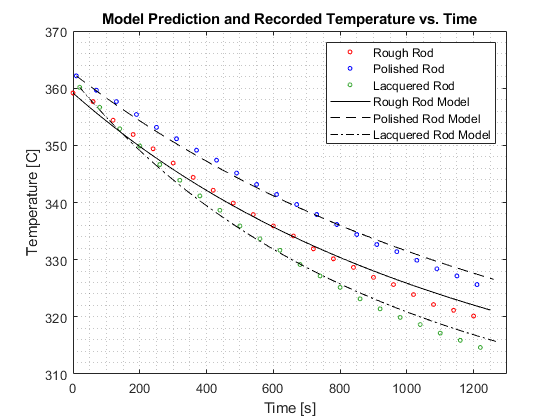

%Plot the Data
fig1 = plot(DataR{:,1},DataR{:,3},'or','markersize',3); hold on
plot(DataP{:,1},DataP{:,3},'ob','markersize',3);
plot(DataL{:,1},DataL{:,3},'o','color',[54/255 166/255 48/255],'markersize',3);
legend('Rough Rod','Polished Rod','Lacquered Rod')
title('Model Prediction and Recorded Temperature vs. Time')
xlabel('Time [s]')
ylabel('Temperature [C]')
grid minor


%Plot the Model
plot(t,T_r,'-k',t+DataP{1,1},T_p,'--k',t+DataL{1,1},T_l,'-.k')
legend('Rough Rod','Polished Rod','Lacquered Rod',...
    'Rough Rod Model','Polished Rod Model','Lacquered Rod Model')
xlim([0,1300])
hold off

e

e =     0.3600    0.0600    0.9200



%Final_Deltas = [T_p(end)-DataP{end,3} T_r(end)-DataR{end,3} T_l(end)-DataL{end,3}]

#### Separated Plots by Rod Type

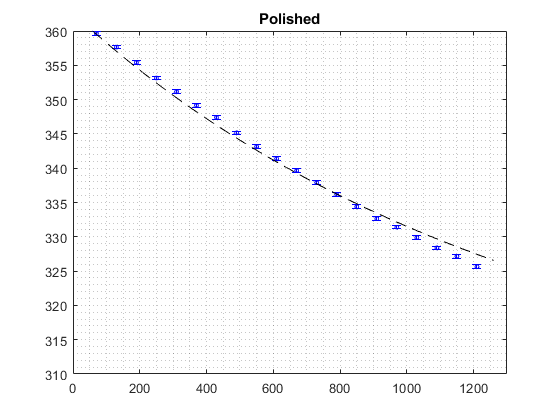

err_p = uncert*ones(size(DataP{:,3}));
err_r = uncert*ones(size(DataR{:,3}));
err_l = uncert*ones(size(DataL{:,3}));


errorbar(DataP{:,1},DataP{:,3},err_p,'ob','markersize',3); hold on
plot(t+DataP{1,1},T_p,'--k')
title('Polished')
xlim([0,1300])
ylim([310,360])
grid minor
hold off

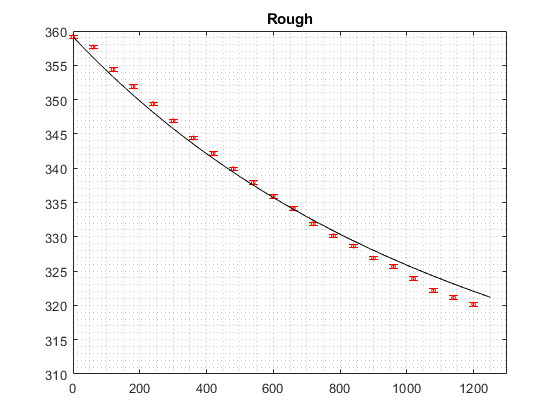



errorbar(DataR{:,1},DataR{:,3},err_r,'or','markersize',3); hold on
plot(t,T_r,'-k')
title('Rough')
xlim([0,1300])
ylim([310,360])
grid minor
hold off

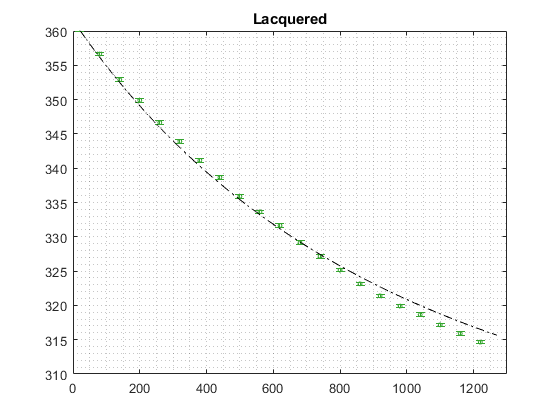



errorbar(DataL{:,1},DataL{:,3},err_l,'o','color',[54/255 166/255 48/255],'markersize',3); hold on
plot(t+DataL{1,1},T_l,'-.k')
title('Lacquered')
xlim([0,1300])
ylim([310,360])
grid minor
hold off

## χ2 Evaluation of Model

%X2 is the sum of the square of the differences divided by the model
%values.

dif_p = DataP{:,3}'-T_p((DataR{:,1})./dt + 1);
X2_p = sum((dif_p.^2)./(uncert^2)) / (length(DataP{:,3})-1);


dif_r = DataR{:,3}'-T_r((DataR{:,1})./dt + 1);
X2_r = sum((dif_r.^2)./(uncert^2)) / (length(DataR{:,3})-1);


dif_l = DataL{:,3}'-T_l((DataR{:,1})./dt + 1);
X2_l = sum((dif_l.^2)./(uncert^2)) / (length(DataL{:,3})-1);

X2 = [X2_p X2_r X2_l]

X2 =    11.9394   22.2160   16.3593


## Residuals

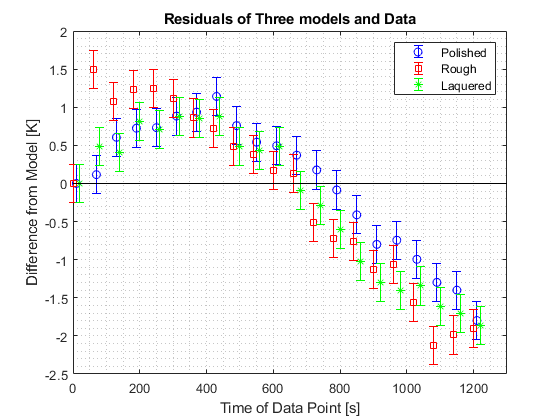

resid_t_p = t((DataP{:,1})./dt + 1);
resid_t_r = t((DataR{:,1})./dt + 1);
resid_t_l = t((DataL{:,1})./dt + 1);
x=linspace(0,1300,100);
y=zeros(1,length(x));


errorbar(resid_t_p,dif_p,err_p,'ob'); hold on
errorbar(resid_t_r,dif_r,err_r,'sr')
errorbar(resid_t_l,dif_l,err_l,'*g')
plot(x,y,'-k')
legend('Polished','Rough','Laquered')
grid minor
xlim([0,x(end)]);
title('Residuals of Three models and Data')
ylabel('Difference from Model [K]')
xlabel('Time of Data Point [s]')